# example for importance sampling of rendering equation (or SRP Ashikhmin–Shirley model)

モンテカルロ積分に使う乱数の数は `nMCint`

`それを nMC `回行って平均と分散を計算し，plotする．（ややこしい）

一応，SRPの計算にも対応（ただし太陽定数とかをかけていない）

clc
clear
cls

format long

## Monte-Carlo condition & pre-allocation

nMC = 10;

srpTrue = zeros(nMC, 3);
srpImp = zeros(nMC, 3);

## Ashikhmin–Shirley model

sat.F0 = 0.5

sat = フィールドをもつ struct :
    F0: 0.500000000000000


sat.mCT = 0.3;


### normal vector

sat.normal = [ 0 0 1 ];
% sat.normal = rand(1,3);
% sat.normal = sat.normal ./ vecnorm(sat.normal,2,2)
thetaN = deg2rad(40);
sat.normal = [0 sin(thetaN) cos(thetaN)];
sat.nu = 100;
sat.nv = 800;
sat.uu = [1 0 0];
sat.uv = cross(sat.normal, sat.uu);

dcm = triad(sat.uu, sat.normal, [1 0 0], [0 0 1]);
sat.qlb = dcm2q(4, dcm);

sat.rho = 0.5;
sat.area = 1;

thetaI = deg2rad(60);
phiI = deg2rad(20);

sunB = [sin(thetaI)*cos(phiI), sin(thetaI)*sin(phiI), cos(thetaI)];
sunB = sunB ./ norm(sunB);


% Monte-Carlo integration condition
nMCintUni = [100, 500, 1000, 5000, 10000, 50000, 100000];
nMCintUni = [10^5 10^6];

tic
for i = 1:length(nMCintUni)
    N = nMCintUni(i);
    for j = 1:nMC

## speuclar only, uniform distribution

        % sampling for sphere region(全球) (note: not hemisphere!)
        thetaR = pi .* rand(N,1); % Nx1
        phiR = 2 * pi .* rand(N,1);

        v = [sin(thetaR).*cos(phiR) sin(thetaR).*sin(phiR) cos(thetaR)]; %Nx3
        h = sunB + v;
        h = h ./ vecnorm(h,2,2); % bisector vector, Nx3

        NH = sat.normal * h'; % nFacet x nMC
        NS = sat.normal * sunB'; % nFacetx1
        VH = dot(v, h, 2)'; % 1xnMC
        NV = sat.normal * v'; % nFacet x nMC, 列方向に各reference vector, vの値

        F = sat.F0 + (1 - sat.F0) .* (1 - VH).^5; % nFacet x nMC
        k1 = sqrt((sat.nu+1) .* (sat.nv+1)) / 8 / pi; % nFacet x 1
        M = 1 ./ VH ./ max(NS, NV); % nFacet x nMC
        k2 = (sat.nu .* (sat.uu * h').^2 + sat.nv .* (sat.uv * h').^2) ./ (1 - NH.^2);
        D = NH .^ k2; % nFacet x nMC

        tmp = k1 .* F .* M .* D .* NV .* sin(thetaR)'; % nFacet x nMC

        csASx = NS .* (NS > 0) .* (NV > 0) .* tmp .* v(:,1)'; % nFacet x nMC matrix
        csASy = NS .* (NS > 0) .* (NV > 0) .* tmp .* v(:,2)';
        csASz = NS .* (NS > 0) .* (NV > 0) .* tmp .* v(:,3)';
      
        % % % for rendering eq.
        % csASx = (NS > 0) .* (NV > 0) .* tmp;
        % csASy = (NS > 0) .* (NV > 0) .* tmp;
        % csASz = (NS > 0) .* (NV > 0) .* tmp;

        % probability
        pdfAS = 1 / pi * 1 / (2 * pi); % scalar

        % specular component, nx3
        srpCs = [sum(csASx, 2), sum(csASy, 2), sum(csASz, 2)];
        srpCs = sum(srpCs,1) ./ pdfAS ./ N;

        srpTrue(j,:) = srpCs;
    end
    stdTrue(i,:) = std(srpTrue);
    meanTrue(i,:) = mean(srpTrue);
end
toc

経過時間は 1.312812 秒です。


## importance sampling

% Monte-Carlo integration condition
% nMCint = 10:200:10000;
nMCintImp = [100 40^4];
nMCintImp = nMCintUni;

tic
for i = 1:length(nMCintImp)
    N = nMCintImp(i);
    for j = 1:nMC


#### transform to local frame

法線ベクトルが${\bf n} =[0, 0, 1]^T
$になるlocal frameへ変換して計算する

        nFacet = size(sat.normal,1); % # of facet

        % sun vector and normal vectors at local frame (normal vector is along z-axis)
        sLocal = qRotation(4, repmat(sunB,nFacet,1), sat.qlb); % nFacet x 3
        nLocal = qRotation(4, sat.normal, sat.qlb); % (for debug), nFacet x 3

        NS = sat.normal * sunB'; % nFacetx1

## sampling

importance sampling for ${\bf{h}} = [\cos\phi_h \sin\theta_h, \sin\phi_h \sin\theta_h, \cos\theta_h]^T$

        u1 = rand(N,1);
        u2 = rand(N,1);

        % phiH = atan(sqrt((sat.nu + 1) / (sat.nv + 1)) * tan(2*pi .* u1));
        % phiH = phiH .* (u1 <= 0.25) + (phiH + pi) .* (u1 > 0.25) .* (u1 < 0.75)...
        %     + (phiH + 2 * pi) .* (u1 >= 0.75);
        
        phiFun = @(u, nu, nv) atan(sqrt((nu + 1) / (nv + 1)) * tan(pi .* u / 2));
        ind1 = (u1 < 0.25);
        ind2 = (u1 >= 0.25) .* (u1 < 0.5);
        ind3 = (u1 >= 0.5) .* (u1 < 0.75);
        ind4 = (u1 >= 0.75);
        
        u1 = ind1 .* 4 .* u1 +  ind2 .* (4 * (u1 -0.25)) ...
            +  ind3 .* (4 * (u1 - 0.5)) + ind4 .* (4 * (u1 - 0.75));

        phiH = phiFun(u1, sat.nu, sat.nv); %一旦,計算
        phiH = ind1 .* phiH  + ind2 .* (phiH + pi/2) ...
            + ind3 .* (phiH + pi) + ind4 .* (phiH + 3/2*pi);            
        
        thetaH = acos((1-u2).^(1 ./ (sat.nu .* cos(phiH).^2 + sat.nv .* sin(phiH).^2 + 1)));

        h = [sin(thetaH).*cos(phiH) sin(thetaH).*sin(phiH) cos(thetaH)]; %Nx3


### integration

        vx = 2 * (sLocal * h') .* h(:,1)' - sLocal(:,1); % nFacet x N
        vy = 2 * (sLocal * h') .* h(:,2)' - sLocal(:,2); % nFacet x N
        vz = 2 * (sLocal * h') .* h(:,3)' - sLocal(:,3); % nFacet x N

        VH = vx .* h(:,1)' + vy .* h(:,2)' + vz .* h(:,3)'; % nFacet x N
        NV = vz; % nFacet x N
        SH = sLocal * h'; % nFacet x N
        NH = h(:,3)'; % nFacet x N

        F = sat.F0 + (1 - sat.F0) .* (1 - VH).^5; % nFacet x nMC

        % weight
        W = abs(SH) .* NV ./ VH ./ NH./ max(NS, NV);        

        temp = W .* F; % nxN

        % for SRP
        csASx = NS .* (NS > 0) .*  (NV > 0) .* temp .* vx; % nFacetxN matrix
        csASy = NS .* (NS > 0) .*  (NV > 0) .* temp .* vy; % nFacetxN matrix
        csASz = NS .* (NS > 0) .*  (NV > 0) .* temp .* vz; % nFacetxN matrix

        % for rendering
        % csASx = (NS > 0) .* (NV > 0) .* temp; % nFacetxN matrix
        % csASy = (NS > 0) .* (NV > 0) .* temp; % nFacetxN matrix
        % csASz = (NS > 0) .* (NV > 0) .* temp; % nFacetxN matrix

        % specular component, nx3
        tmp = [mean(csASx,2), mean(csASy,2), mean(csASz,2)];
        tmp = qRotation(4, tmp, qInv(4, sat.qlb)); % transform back to the original body-fixed frame, nFacet x 3        

        sunlitFlag = (NS > 0); % nFacet x 1 matrix, 1: sunlit, 0: shade
        tmp = sat.area .*  sunlitFlag .* tmp;
        srpImp(j,:) = sum(tmp, 1);
    end

    stdImp(i,:) = std(srpImp);
    meanImp(i,:) = mean(srpImp);
end

toc

経過時間は 1.364322 秒です。


## show FIgs

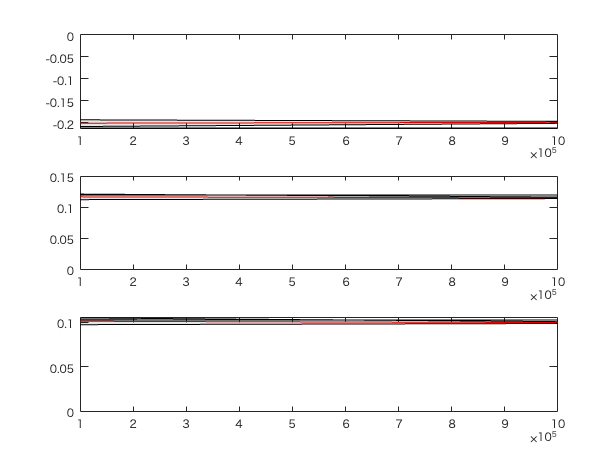

figure
tiledlayout(3,1), nexttile
plotStd(nMCintUni, meanTrue(:,1), stdTrue(:,1), 'r'), hold on
plotStd(nMCintImp, meanImp(:,1), stdImp(:,1), 'b', 'b');

nexttile
plotStd(nMCintUni, meanTrue(:,2), stdTrue(:,2)); hold on
plotStd(nMCintImp, meanImp(:,2), stdImp(:,2),'b', 'b');

nexttile
plotStd(nMCintUni, meanTrue(:,3), stdTrue(:,3)); hold on
plotStd(nMCintImp, meanImp(:,3), stdImp(:,3), 'b', 'b');

### mean and standard deviation

[meanTrue(end,:)
    meanImp(end,:)]

ans =   -0.199633804097405   0.114996362922158   0.099727310990734
  -0.212743471372301   0.119489538233053   0.102662178221165



[norm(meanTrue(end,:))
    norm(meanImp(end,:))]

ans =    0.251044529478673
   0.264720715464052
